Path_Name = 'M0_G0_LA1+LA2_RA0';
Sample_Name = 'Sample_1';
Path = strcat(cd,'/',Path_Name,'/',Sample_Name); % 设置数据存放的文件夹路径
File = dir(fullfile(Path,'*.csv'));              % 显示文件夹下所有符合后缀名为.txt文件的完整信息
FileNames = {File.name}'                       % 提取符合后缀名为.txt的所有文件的文件名，转换为n行1列

FileNames = 4×1 cell 数组
    {'data_gearbox_M0_G0_LA1+LA2_RA0_20Hz_0kN.csv'     }
    {'data_leftaxlebox_M0_G0_LA1+LA2_RA0_20Hz_0kN.csv' }
    {'data_motor_M0_G0_LA1+LA2_RA0_20Hz_0kN.csv'       }
    {'data_rightaxlebox_M0_G0_LA1+LA2_RA0_20Hz_0kN.csv'}


Name = strcat(cd,'/',Path_Name,'/',Sample_Name,'/',FileNames{2});
DataRead1 = csvread(Name,1,0);

x = DataRead1(1:64000,1);
fs = 64e3;
t = (0:length(x) - 1)' / fs;

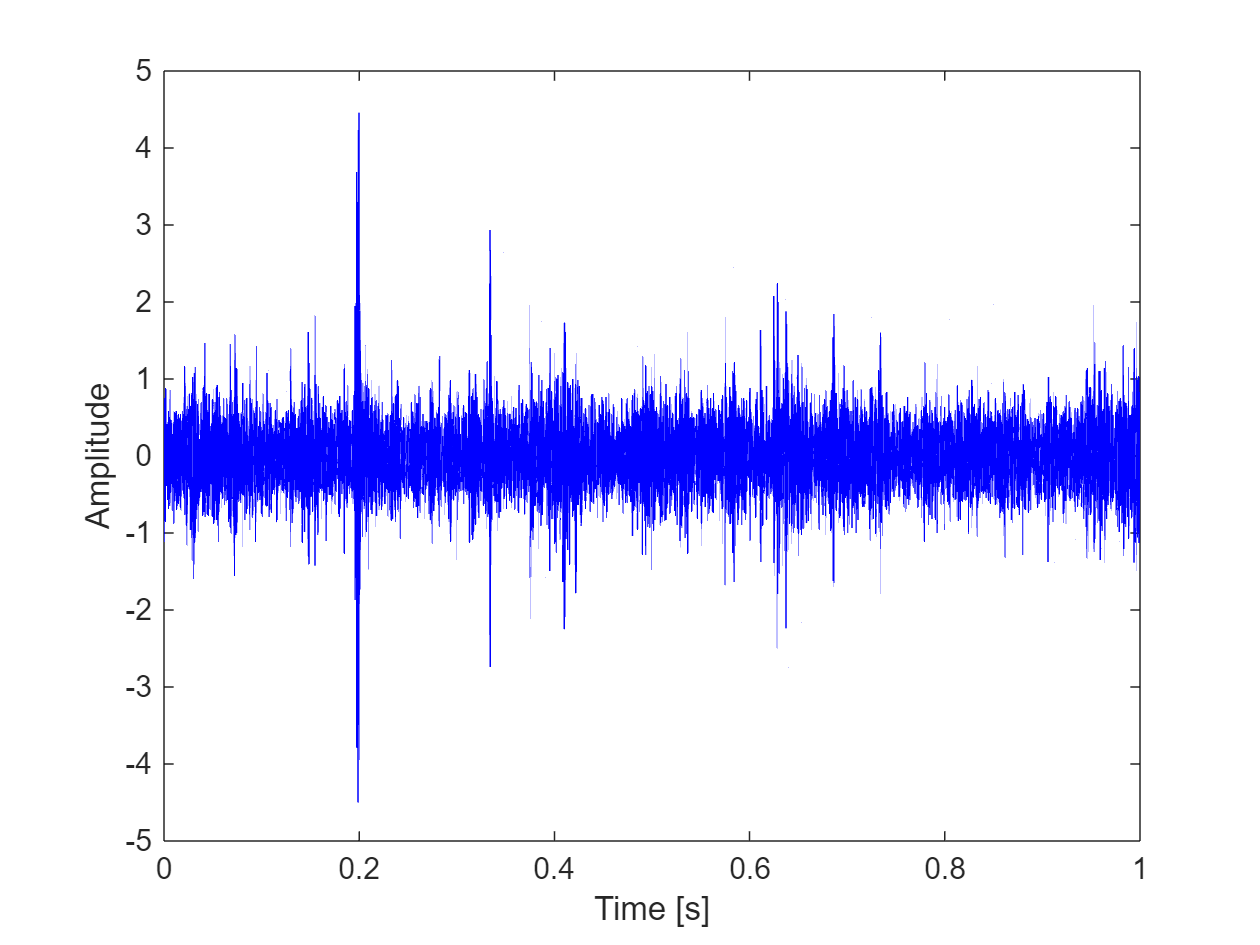


%%
figure('Name', 'Time waveform of mixed signal')
plot(t, x, 'b');
xlabel('Time [s]');
ylabel('Amplitude');

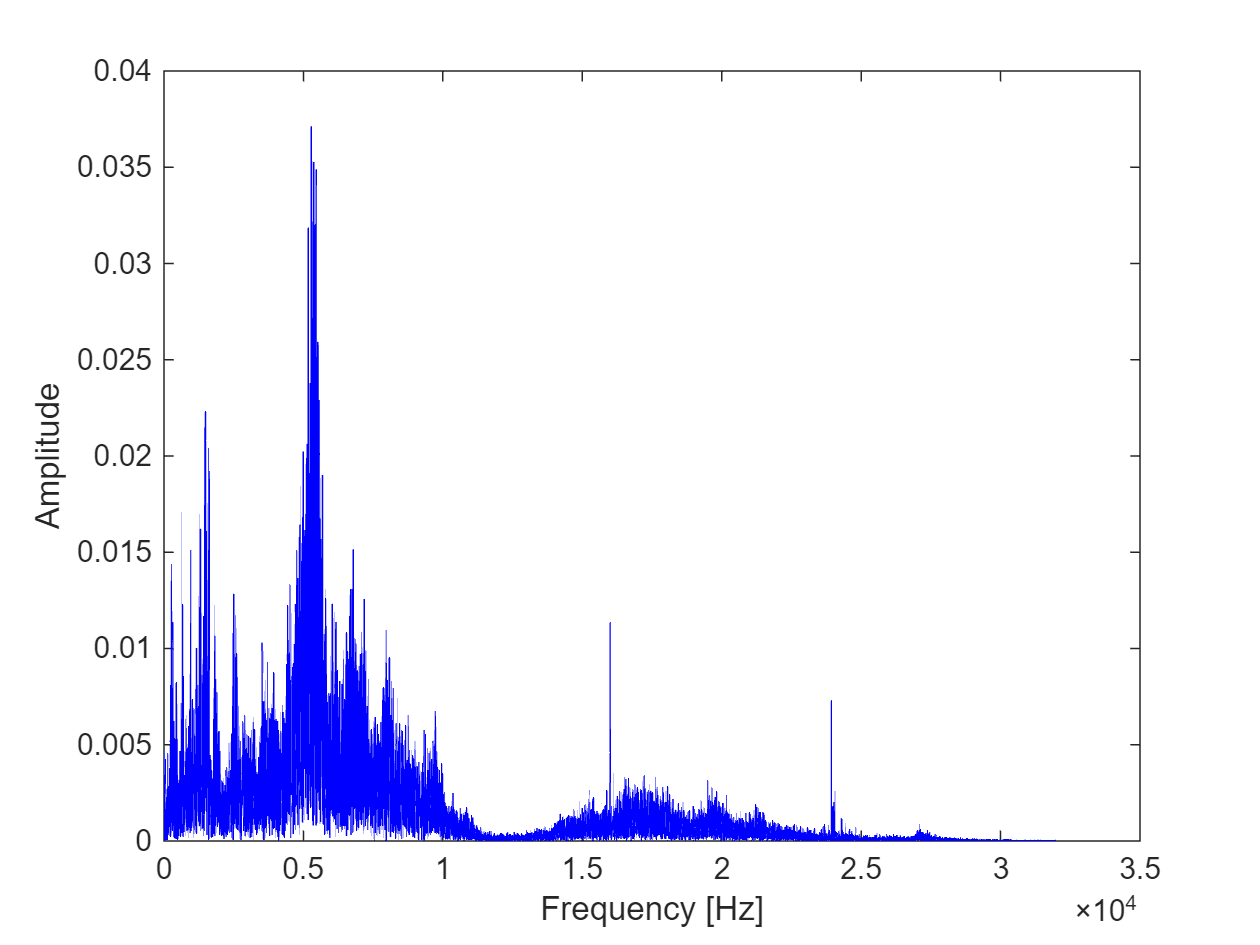


figure('Name', 'FFT amplitude spectrum of mixed signal')
[~, ~] = myfft(fs, x, 1);
xlabel('Frequency [Hz]');
ylabel('Amplitude');


%% Parameters
filtersize = 10;
cutnum = 9;
modenum = 2;
maxiternum = 50;

% FMD
tic
y_final = FMD(fs, x, filtersize, cutnum, modenum, maxiternum);
toc

历时 12.109008 秒。


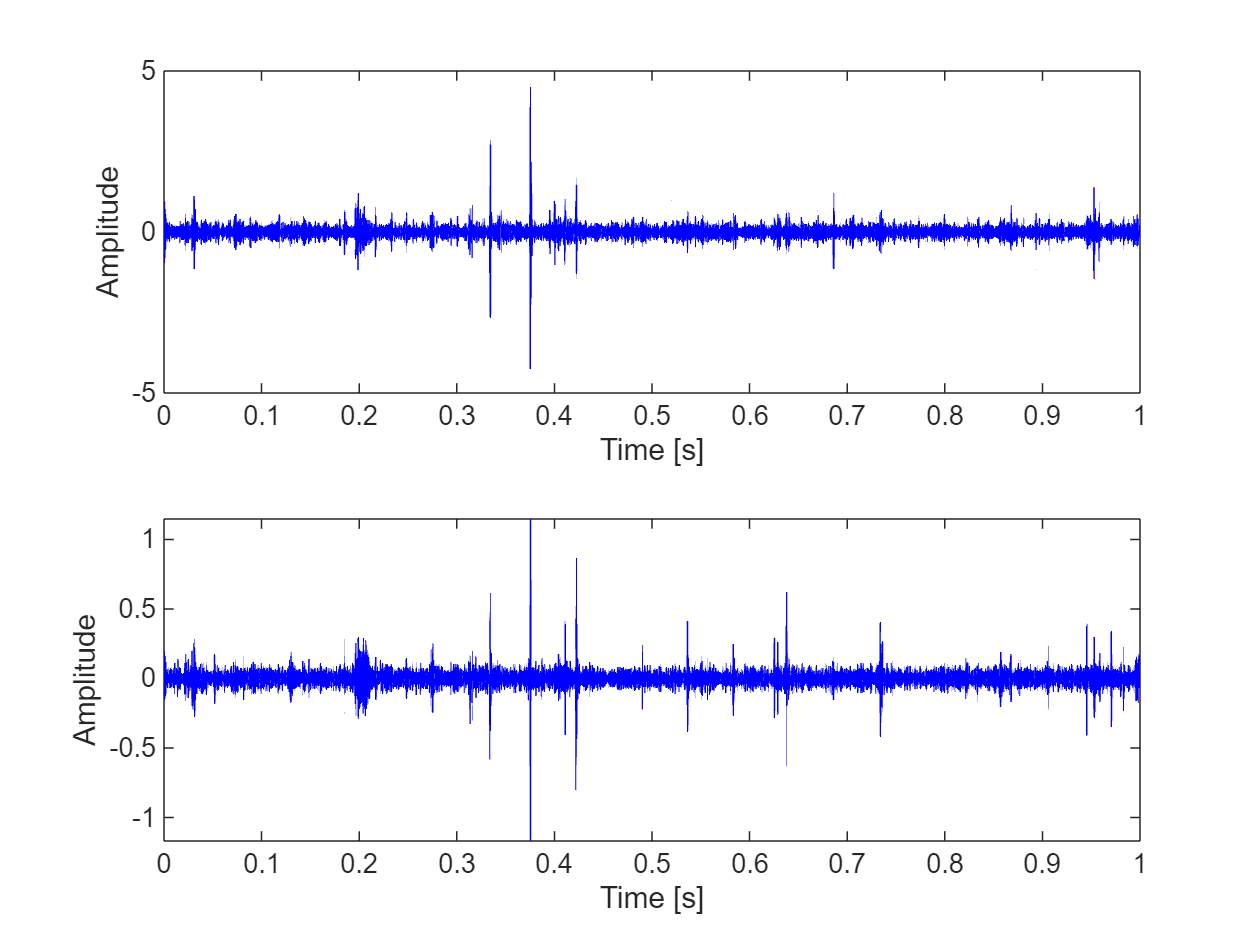

% Plot
b = size(y_final, 2);

figure('Name', 'Time waveform of mode(s)')
for k = 1:b
    subplot(b, 1, k)
    plot(t, y_final(:, k), 'b')
    xlabel('Time [s]');
    ylabel('Amplitude');
end

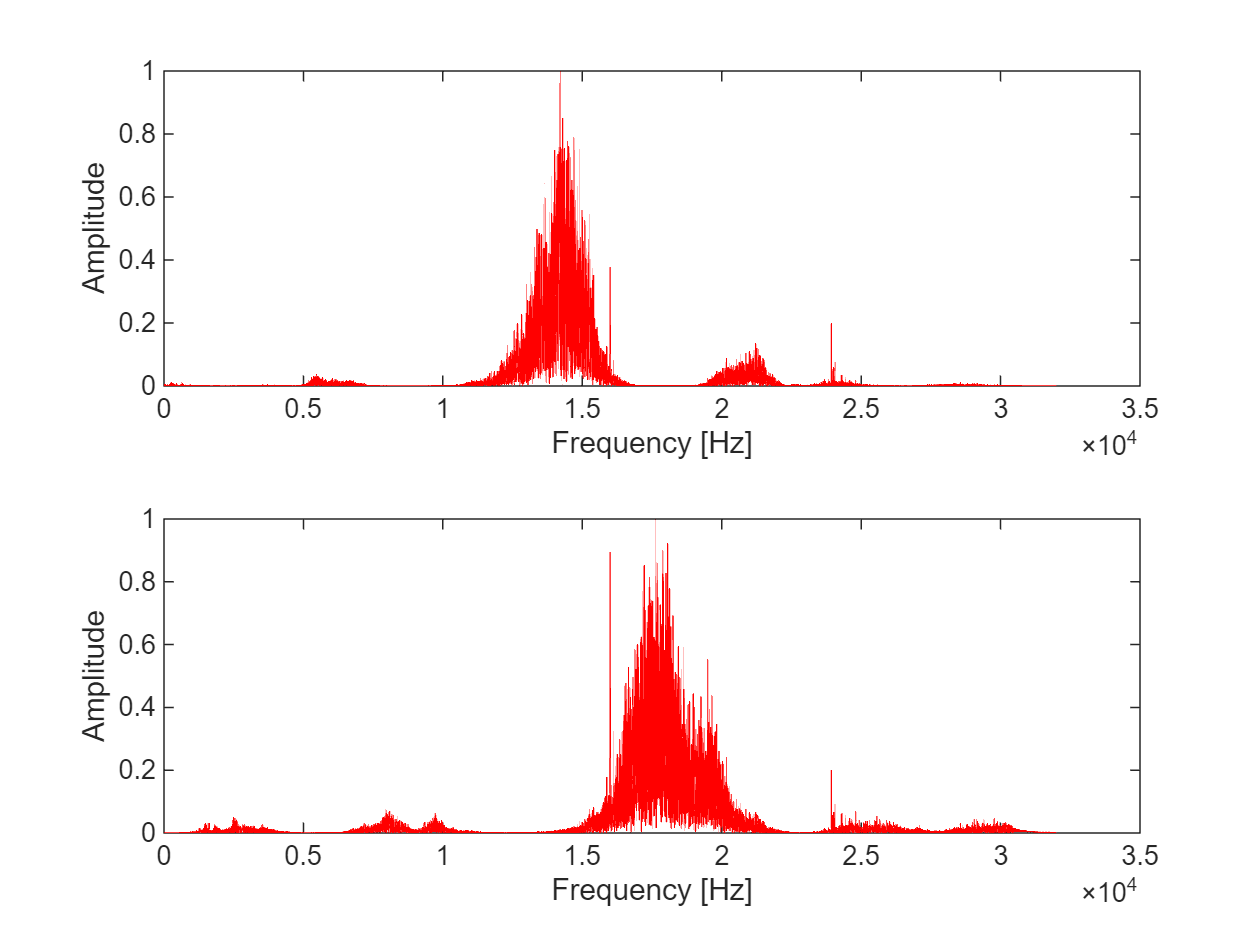


figure('Name', 'FFT amplitude spectrum of mode(s)')
for k = 1:b
    subplot(b, 1, k)
    [ff, amp] = myfft(fs, y_final(:, k), 0);
    plot(ff, amp / max(amp), 'r');
    xlabel('Frequency [Hz]');
    ylabel('Amplitude');
end

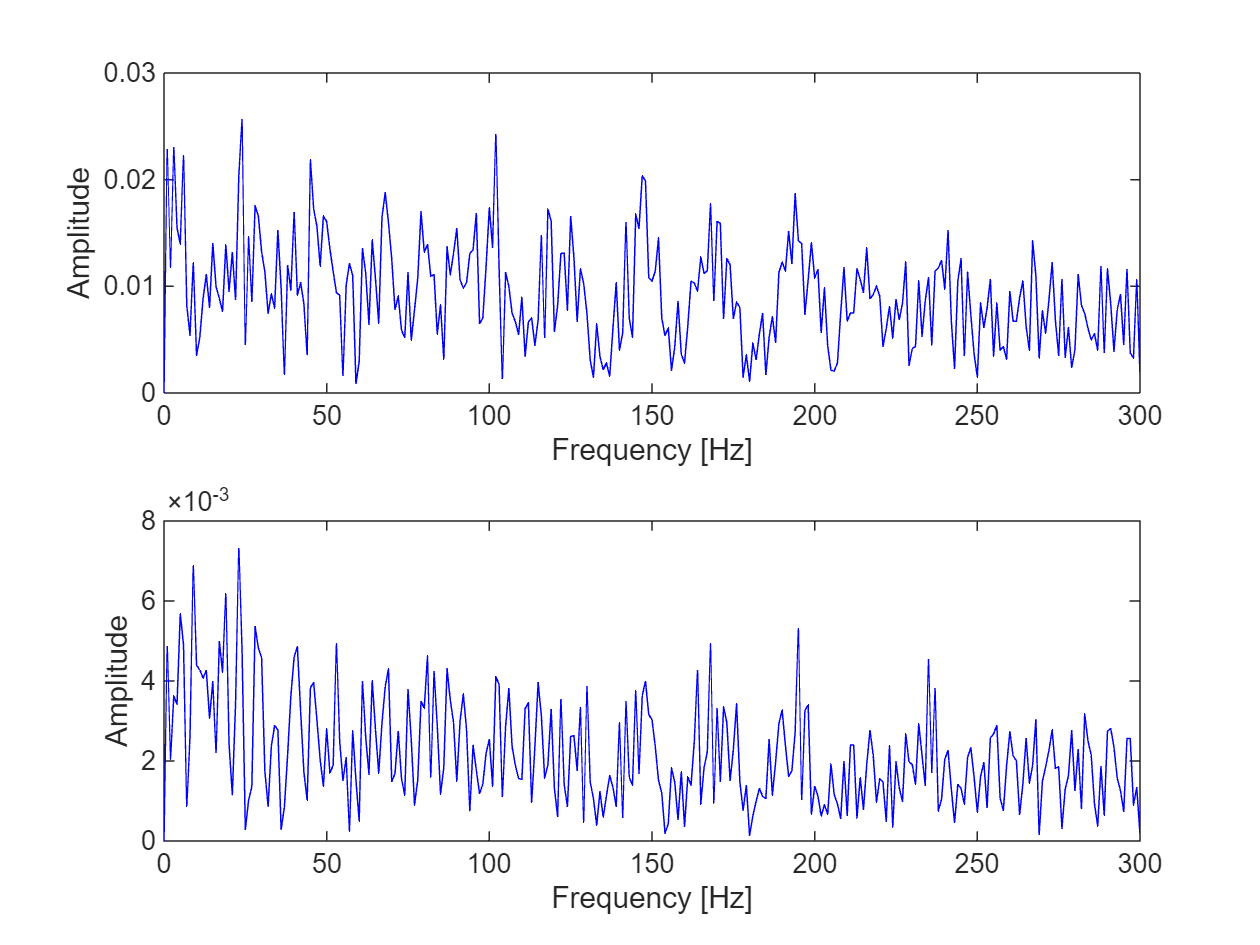


figure('Name', 'Hilbert envelope spectrum of mode(s)')
for k = 1:b
    subplot(b, 1, k)
    envelope = abs(hilbert(y_final(:, k))) - mean(abs(hilbert(y_final(:, k))));
    [ff, amp] = myfft(fs, envelope, 1);
    xlabel('Frequency [Hz]');
    ylabel('Amplitude');
    xlim([0 300])
end

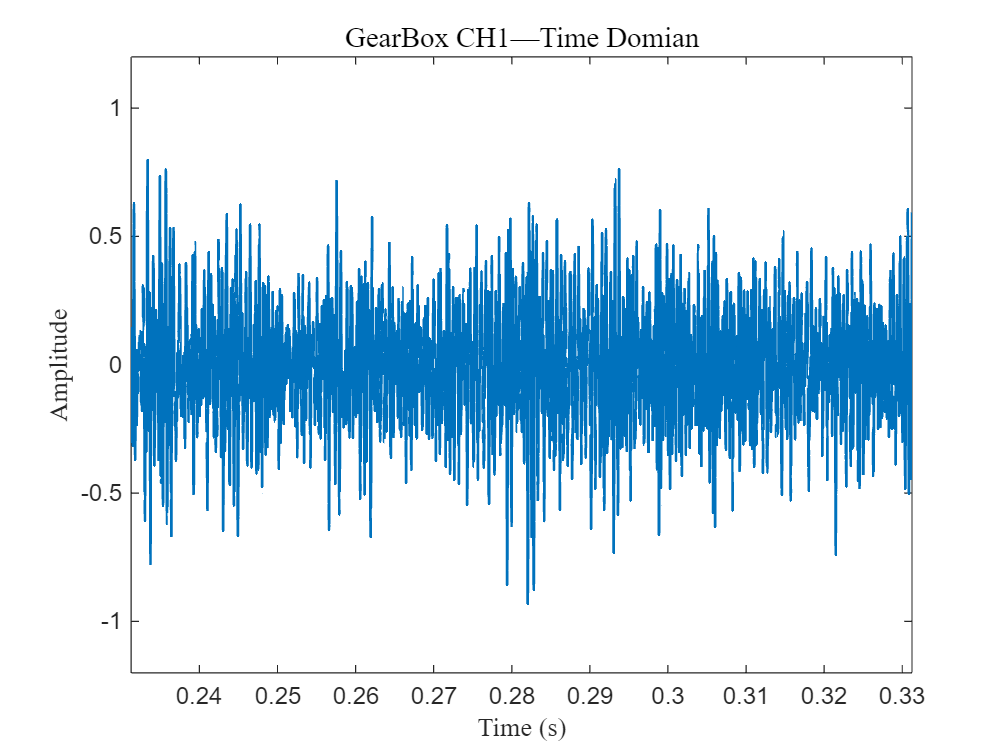

if exist("ChannelName")
    clear ChannelName
    clear DataSplit
end

ChannelNum = [1];
for i = 1:length(ChannelNum)
    ChannelName(i) = {['CH',num2str(ChannelNum(i))]};
end

figure
fs = 64000;
L = 6400;
Start = 14800;
T = (Start+1:Start+L)/fs;
Data1 = DataRead1(Start+1:Start+L,ChannelNum)-movmean(DataRead1(Start+1:Start+L,ChannelNum),L/100);
plot(T,Data1,LineWidth=1.1);
ylim([-1.2 1.2])
xlim([T(1) T(end)])
title(['GearBox CH' num2str(ChannelNum) '—Time Domian'],FontName='Times New Roman',FontSize=12)
xlabel('Time (s)',FontName='Times New Roman')
ylabel('Amplitude',FontName='Times New Roman')

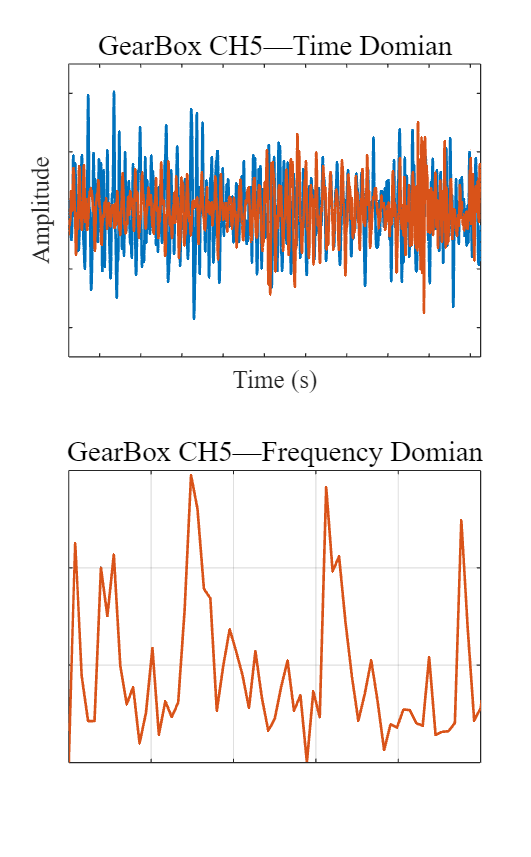

fs = 64000;
L = 3200;
Start = 14800;
T = (Start+1:Start+L)/fs;

% Data1 = RandNFilter(10,DataRead1(Start+1:Start+L,ChannelNum)+(rand(L,1)-0.5)*0.8);
% Data2 = RandNFilter(10,DataRead2(Start+1:Start+L,ChannelNum)+(rand(L,1)-0.5)*0.8);
Data1 = DataRead1(Start+1:Start+L,ChannelNum);
Data2 = DataRead2(Start+1:Start+L,ChannelNum);
[OutputA1,OutputF1] = hua_baol(Data1,fs,1);
[OutputA2,OutputF2] = hua_baol(Data1,fs,1);
figure
subplot(211)
t = linspace(0,L/fs,L);
plot(T,Data1,LineWidth=1.1);
hold on
plot(T,Data2,LineWidth=1.1);
ylim([-2.5 2.5])
xlim([T(1) T(end)])
title(['GearBox CH' num2str(ChannelNum) '—Time Domian'],FontName='Times New Roman',FontSize=12)
xlabel('Time (s)',FontName='Times New Roman')
ylabel('Amplitude',FontName='Times New Roman')
% legend('Composite Fault Signal',"BackgroundAlpha",0.6,Orientation="horizontal",Location="northeast",box = 'off')
grid off
xticklabels ''
yticklabels ''

subplot(212)
plot(OutputF1,OutputA1,LineWidth=1.1)
hold on
plot(OutputF2,OutputA2,LineWidth=1.1)
xlim([0 1000])
grid on
title(['GearBox CH' num2str(ChannelNum) '—Frequency Domian'],FontName='Times New Roman',FontSize=12)
% ylabel('Amplitude',FontName='Times New Roman')
% legend('Real Signal','Generated Signal',"BackgroundAlpha",0.6,Orientation="horizontal",Location="northeast")

set(gcf,'unit','pixel','position',[231.5,213.5,295,476]);
xticklabels ''
yticklabels ''

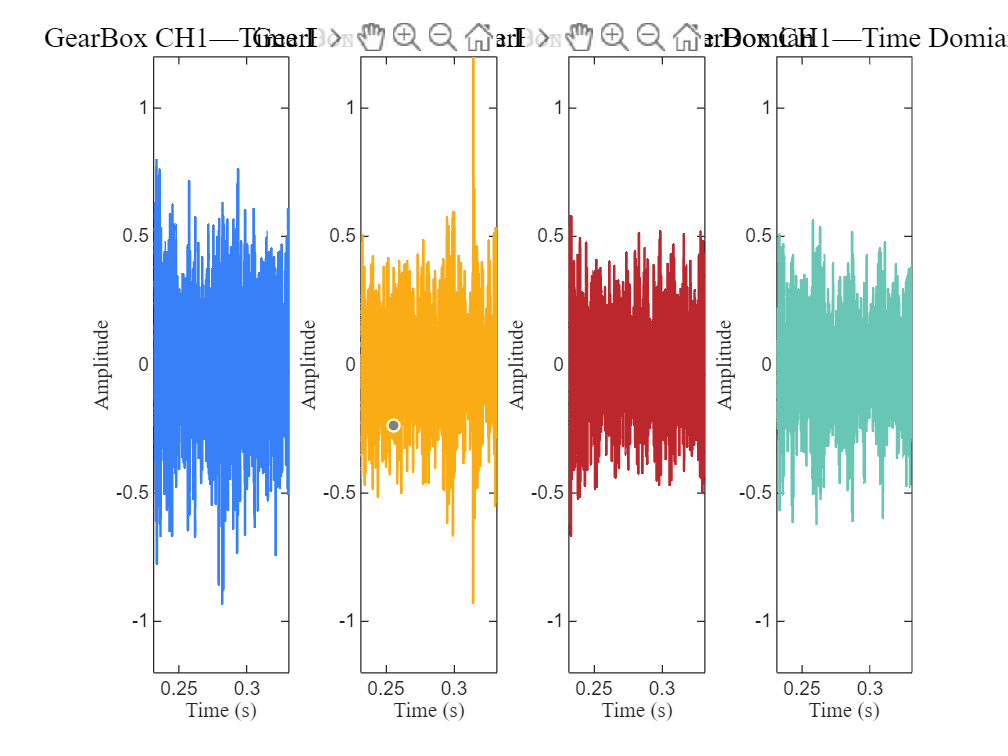

figure
Clist = {'#3780F7','#FAAC14','#BB272C','#67C6B4'};
for idx = 1:4
    subplot(1,4,idx)
    Path_Name = strcat('M0_G0_LA',num2str(idx-1),'_RA0');
    Sample_Name = 'Sample_1';
    Path = strcat(cd,'/',Path_Name,'/',Sample_Name); % 设置数据存放的文件夹路径
    File = dir(fullfile(Path,'*.csv'));              % 显示文件夹下所有符合后缀名为.txt文件的完整信息
    FileNames = {File.name}';                       % 提取符合后缀名为.txt的所有文件的文件名，转换为n行1列
    Name = strcat(cd,'/',Path_Name,'/',Sample_Name,'/',FileNames{1});
    DataRead1 = csvread(Name,1,0);
    if exist("ChannelName")
        clear ChannelName
        clear DataSplit
    end
    ChannelNum = [1];
    for i = 1:length(ChannelNum)
        ChannelName(i) = {['CH',num2str(ChannelNum(i))]};
    end

    fs = 64000;
    L = 6400;
    Start = 14800;
    T = (Start+1:Start+L)/fs;
    Data1 = DataRead1(Start+1:Start+L,ChannelNum)-movmean(DataRead1(Start+1:Start+L,ChannelNum),L/100);
    plot(T,Data1,LineWidth=1.1,Color=Clist{idx});
    ylim([-1.2 1.2])
    xlim([T(1) T(end)])
    title(['GearBox CH' num2str(ChannelNum) '—Time Domian'],FontName='Times New Roman',FontSize=12)
    xlabel('Time (s)',FontName='Times New Roman')
    ylabel('Amplitude',FontName='Times New Roman')
end

figure
Clist = {'#3780F7','#FAAC14','#BB272C','#67C6B4'};
Path_Name = strcat('M0_G0_LA2+LA4_RA0');
Sample_Name = 'Sample_1';
Path = strcat(cd,'/',Path_Name,'/',Sample_Name); % 设置数据存放的文件夹路径
File = dir(fullfile(Path,'*.csv'));              % 显示文件夹下所有符合后缀名为.txt文件的完整信息
FileNames = {File.name}';                       % 提取符合后缀名为.txt的所有文件的文件名，转换为n行1列
Name = strcat(cd,'/',Path_Name,'/',Sample_Name,'/',FileNames{1});
DataRead2 = csvread(Name,1,0);
if exist("ChannelName")
    clear ChannelName
    clear DataSplit
end
ChannelNum = [1];
for i = 1:length(ChannelNum)
    ChannelName(i) = {['CH',num2str(ChannelNum(i))]};
end

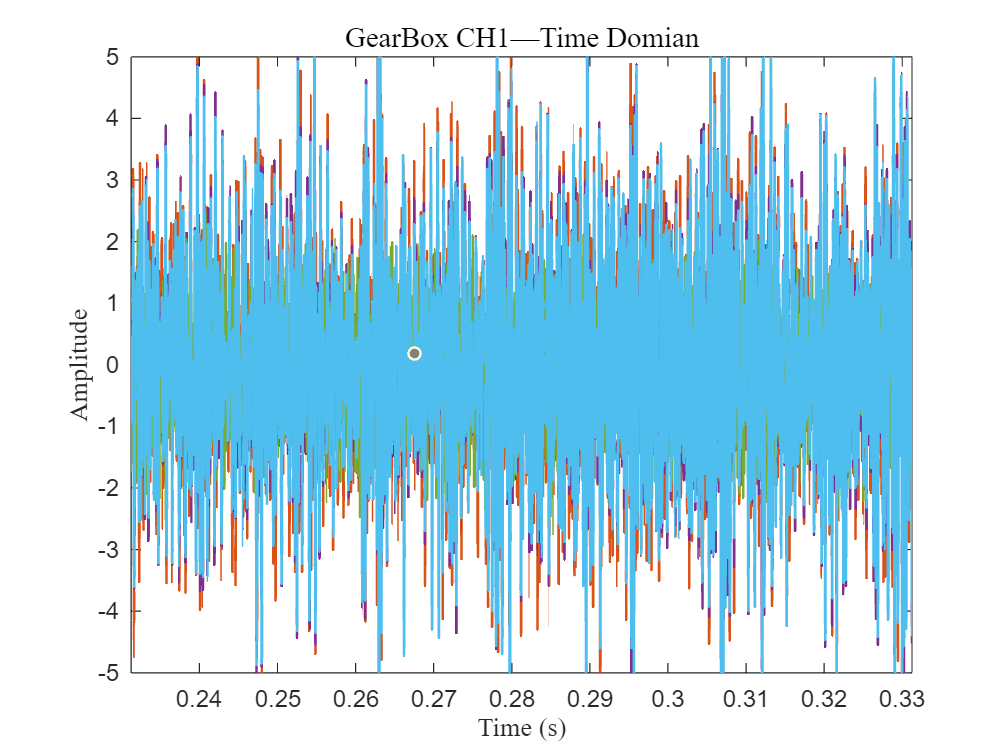


fs = 64000;
L = 6400;
Start = 14800;
T = (Start+1:Start+L)/fs;
Data2 = DataRead2(Start+1:Start+L,ChannelNum)-movmean(DataRead2(Start+1:Start+L,ChannelNum),L/100)+0.1*randn(size(DataRead2(Start+1:Start+L,ChannelNum)));
plot(T,Data1,LineWidth=1.1);
hold on
plot(T,Data2,LineWidth=1.1);
ylim([-5 5])
xlim([T(1) T(end)])
title(['GearBox CH' num2str(ChannelNum) '—Time Domian'],FontName='Times New Roman',FontSize=12)
xlabel('Time (s)',FontName='Times New Roman')
ylabel('Amplitude',FontName='Times New Roman')

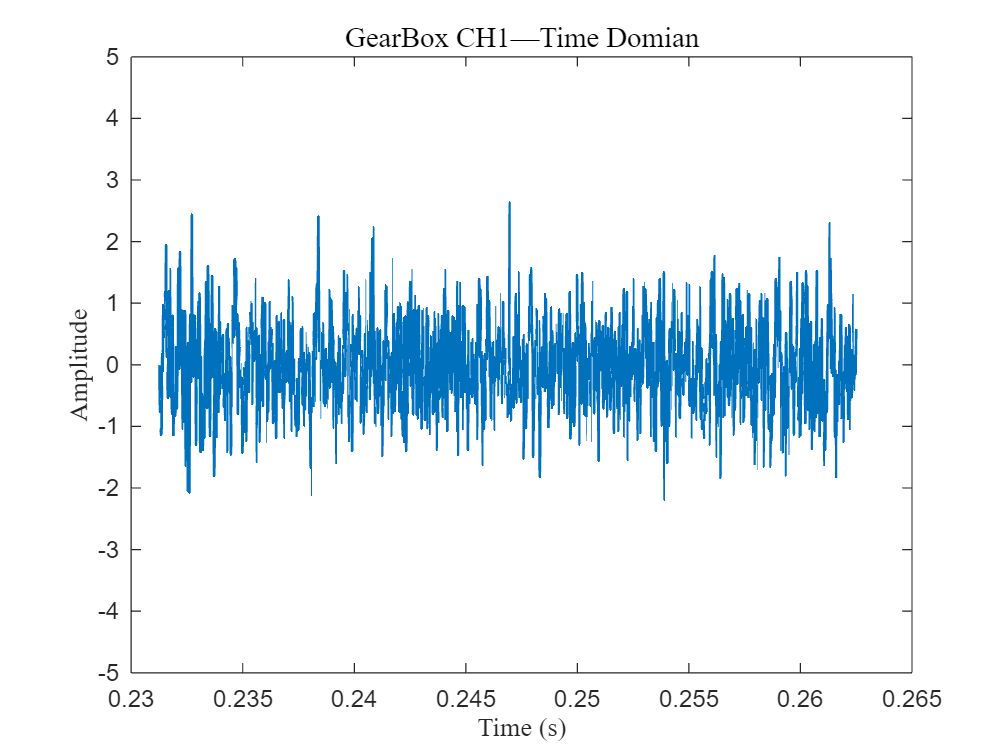

filtered_signal = RandNFilter(7,Data1);
figure
plot(T(1:2000),filtered_signal(1:2000),LineWidth=1.1);
ylim([-5 5])

title(['GearBox CH' num2str(ChannelNum) '—Time Domian'],FontName='Times New Roman',FontSize=12)
xlabel('Time (s)',FontName='Times New Roman')
ylabel('Amplitude',FontName='Times New Roman')

function filtered_signal = RandNFilter(N,input_signal)
    % 采样频率
    Fs = 64000;  % 32 kHz
    
    % 生成随机频段的中心频率
    num_bands = N;
    center_frequencies = sort(randperm(31400, num_bands) + 600);  % 确保频段在 200 Hz 到 31800 Hz 之间
    IterativeSignal = input_signal;
    % 设计高通滤波器
    for i = 1:num_bands
        % 中心频率
        fc = center_frequencies(i);
        
        % 频段范围 [fc - 200 Hz, fc + 200 Hz]
        f_low = fc - 600;  % 下限频率
        f_high = fc + 600; % 上限频率
        
        % 设计带通滤波器（高通滤波器的变种）
        [b, a] = butter(4, [f_low, f_high]/(Fs/2), "stop");  % 4阶Butterworth带通滤波器
        
        % 你可以在这里应用滤波器到你的信号上
        IterativeSignal = filter(b, a, IterativeSignal);
        
    end
    filtered_signal = IterativeSignal;
end